%% ================================================================
%  ANÁLISE E TRANSFORMAÇÃO DE DADOS – PROJETO 2026
%  Meta 1 – Pontos 1 ao 7
%
%  Estrutura esperada:
%    data/
%      01/
%        0_01_0.wav   <- digito=0, participante=01, repeticao=0
%        ...
%
%  IMPORTANTE: coloque este script na mesma pasta onde está a pasta data/
%  As funções locais estão no FINAL deste ficheiro (obrigatório MATLAB).
% ================================================================

clear; clc; close all;

DATA_PATH = fullfile('data');

%% ================================================================
%  PONTO 1 – Criação da Estrutura de Dados
% ================================================================
fprintf('=== PONTO 1: Criação da estrutura de dados ===\n');

=== PONTO 1: Criação da estrutura de dados ===



if ~isfolder(DATA_PATH)
    error('Pasta "%s" não encontrada. Ajuste a variável DATA_PATH.', DATA_PATH);
end

participant_dirs = dir(DATA_PATH);
participant_dirs = participant_dirs([participant_dirs.isdir]);
participant_dirs = participant_dirs(~ismember({participant_dirs.name},{'.','..'}));

fprintf('Sub-pastas encontradas: %d\n', numel(participant_dirs));

Sub-pastas encontradas: 60



directory    = {};
filename_col = {};
participant  = [];
digit_col    = [];
repetition   = [];

for p = 1:numel(participant_dirs)
    part_path = fullfile(DATA_PATH, participant_dirs(p).name);
    wav_files = dir(fullfile(part_path, '*.wav'));

    for f = 1:numel(wav_files)
        fname = wav_files(f).name;
        parts = strsplit(fname(1:end-4), '_');

        if numel(parts) < 3
            warning('Nome inesperado: %s — ignorado.', fname);
            continue;
        end

        directory{end+1,1}   = part_path;
        filename_col{end+1,1}= fname;
        digit_col(end+1,1)   = str2double(parts{1});
        participant(end+1,1) = str2double(parts{2});
        repetition(end+1,1)  = str2double(parts{3});
    end
end

T = table(directory, filename_col, participant, digit_col, repetition, ...
    'VariableNames',{'Directory','Filename','Participant','Digit','Repetition'});
T = sortrows(T, {'Participant','Digit','Repetition'});

fprintf('Total de ficheiros  : %d\n',   height(T));

Total de ficheiros  : 30000


fprintf('Participantes       : %d\n',   numel(unique(T.Participant)));

Participantes       : 60


fprintf('Dígitos             : %s\n',   num2str(unique(T.Digit)'));

Dígitos             : 0  1  2  3  4  5  6  7  8  9


fprintf('Repetições por díg. : %d\n\n', numel(unique(T.Repetition)));

Repetições por díg. : 50



disp(head(T, 5));

     Directory        Filename       Participant    Digit    Repetition
    ___________    ______________    ___________    _____    __________

    {'data\01'}    {'0_01_0.wav'}         1           0          0     
    {'data\01'}    {'0_01_1.wav'}         1           0          1     
    {'data\01'}    {'0_01_2.wav'}         1           0          2     
    {'data\01'}    {'0_01_3.wav'}         1           0          3     
    {'data\01'}    {'0_01_4.wav'}         1           0          4     




%% ================================================================
%  PONTO 2 – Importação dos Sinais de Áudio
% ================================================================
fprintf('=== PONTO 2: Importação dos sinais de áudio ===\n');

=== PONTO 2: Importação dos sinais de áudio ===



N_files      = height(T);
signals      = cell(N_files, 1);
sample_rates = zeros(N_files, 1);

for i = 1:N_files
    filepath  = fullfile(T.Directory{i}, T.Filename{i});
    [sig, fs] = audioread(filepath);

    if size(sig, 2) > 1, sig = sig(:, 1); end

    signals{i}      = double(sig);
    sample_rates(i) = fs;

    if mod(i, 1000) == 0
        fprintf('  Carregados %d / %d ficheiros...\n', i, N_files);
    end
end

  Carregados 1000 / 30000 ficheiros...
  Carregados 2000 / 30000 ficheiros...
  Carregados 3000 / 30000 ficheiros...
  Carregados 4000 / 30000 ficheiros...
  Carregados 5000 / 30000 ficheiros...
  Carregados 6000 / 30000 ficheiros...
  Carregados 7000 / 30000 ficheiros...
  Carregados 8000 / 30000 ficheiros...
  Carregados 9000 / 30000 ficheiros...
  Carregados 10000 / 30000 ficheiros...
  Carregados 11000 / 30000 ficheiros...
  Carregados 12000 / 30000 ficheiros...
  Carregados 13000 / 30000 ficheiros...
  Carregados 14000 / 30000 ficheiros...
  Carregados 15000 / 30000 ficheiros...
  Carregados 16000 / 30000 ficheiros...
  Carregados 17000 / 30000 ficheiros...
  Carregados 18000 / 30000 ficheiros...
  Carregados 19000 / 30000 ficheiros...
  Carregados 20000 / 30000 ficheiros...
  Carregados 21000 / 30000 ficheiros...
  Carregados 22000 / 30000 ficheiros...
  Carregados 23000 / 30000 ficheiros...
  Carregados 24000 / 30000 ficheiros...
  Carregados 25000 / 30000 ficheiros...
  Carrega


T.SampleRate = sample_rates;
T.Signal     = signals;

durations = cellfun(@numel, signals) ./ sample_rates;
fprintf('Taxa de amostragem : %d Hz\n',    T.SampleRate(1));

Taxa de amostragem : 48000 Hz


fprintf('Duração mínima     : %.3f s\n',   min(durations));

Duração mínima     : 0.293 s


fprintf('Duração máxima     : %.3f s\n',   max(durations));

Duração máxima     : 1.000 s


fprintf('Duração média      : %.3f s\n\n', mean(durations));

Duração média      : 0.643 s




%% ================================================================
%  PONTO 3 – Representação Gráfica dos Sinais Originais
%  Exemplo: repetição 5, participante 1
% ================================================================
fprintf('=== PONTO 3: Gráficos dos sinais originais ===\n');

=== PONTO 3: Gráficos dos sinais originais ===


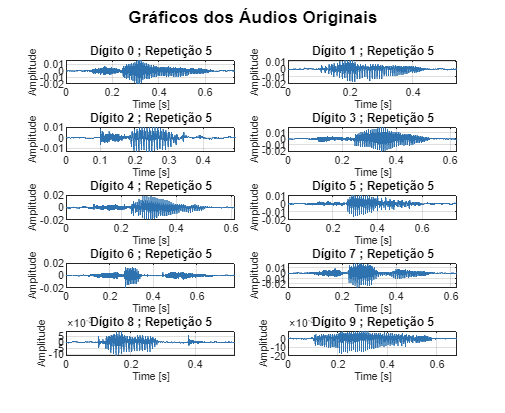


REP_EXAMPLE  = 5;
PART_EXAMPLE = 1;

mask   = (T.Repetition == REP_EXAMPLE) & (T.Participant == PART_EXAMPLE);
subset = sortrows(T(mask,:), 'Digit');

if height(subset) == 0
    error('Nenhum sinal encontrado para repetição=%d e participante=%d.', ...
          REP_EXAMPLE, PART_EXAMPLE);
end

figure('Name','Gráficos dos Áudios Originais', ...
       'NumberTitle','off', 'Position',[50 50 1100 900]);
sgtitle('Gráficos dos Áudios Originais', 'FontSize',13, 'FontWeight','bold');

for i = 1:height(subset)
    sig = subset.Signal{i};
    fs  = subset.SampleRate(i);
    t   = (0:numel(sig)-1) / fs;

    subplot(5, 2, i);
    plot(t, sig, 'Color',[0.18 0.45 0.69], 'LineWidth',0.5);
    title(sprintf('Dígito %d ; Repetição %d', subset.Digit(i), REP_EXAMPLE), ...
          'FontSize',9, 'FontWeight','bold');
    xlabel('Time [s]', 'FontSize',8);
    ylabel('Amplitude', 'FontSize',8);
    xlim([0, t(end)]); grid on;
end


idx_play = find(T.Digit==0 & T.Repetition==REP_EXAMPLE & T.Participant==PART_EXAMPLE, 1);
if ~isempty(idx_play)
    fprintf('A reproduzir: dígito 0, repetição %d, participante %d\n\n', ...
            REP_EXAMPLE, PART_EXAMPLE);
    sound(T.Signal{idx_play}, T.SampleRate(idx_play));
end

A reproduzir: dígito 0, repetição 5, participante 1




%% ================================================================
%  PONTO 4 – Pré-processamento dos Sinais
%   a) Remover silêncio inicial via energia por janelas
%   b) Normalizar amplitude para [-1, 1]
%   c) Uniformizar duração (padding/trimming)
% ================================================================
fprintf('=== PONTO 4: Pré-processamento ===\n');

=== PONTO 4: Pré-processamento ===



WINDOW_MS     = 10;      % tamanho de janela para energia (ms)
ENERGY_THRESH = 0.001;   % limiar (fracção da energia máxima)

% Calcular duração alvo: percentil 95 das durações após remover silêncio
fprintf('  A calcular duração alvo...\n');

  A calcular duração alvo...


trimmed_lens = zeros(N_files, 1);
for i = 1:N_files
    s = remove_silence(T.Signal{i}, T.SampleRate(i), WINDOW_MS, ENERGY_THRESH);
    trimmed_lens(i) = numel(s);
end
target_s   = prctile(trimmed_lens ./ T.SampleRate, 95);
target_len = round(target_s * T.SampleRate(1));
fprintf('  Duração alvo (percentil 95): %.4f s  (%d amostras)\n', target_s, target_len);

  Duração alvo (percentil 95): 0.8197 s  (39345 amostras)



% Aplicar pré-processamento
fprintf('  A pré-processar %d sinais...\n', N_files);

  A pré-processar 30000 sinais...


preprocessed = cell(N_files, 1);
for i = 1:N_files
    sig = remove_silence(T.Signal{i}, T.SampleRate(i), WINDOW_MS, ENERGY_THRESH);
    sig = norm_amplitude(sig);
    sig = pad_trim(sig, target_len);
    preprocessed{i} = sig;

    if mod(i, 5000) == 0
        fprintf('  %d / %d sinais processados...\n', i, N_files);
    end
end

  5000 / 30000 sinais processados...
  10000 / 30000 sinais processados...
  15000 / 30000 sinais processados...
  20000 / 30000 sinais processados...
  25000 / 30000 sinais processados...
  30000 / 30000 sinais processados...



T.SignalPreprocessed = preprocessed;
fprintf('  Concluído! Todos os sinais com %d amostras (%.3f s)\n\n', ...
        target_len, target_len / T.SampleRate(1));

  Concluído! Todos os sinais com 39345 amostras (0.820 s)




%% ================================================================
%  PONTO 5 – Gráficos dos Sinais Pré-processados
%  (repetição 5, participante 1 — igual ao ponto 3)
% ================================================================
fprintf('=== PONTO 5: Gráficos dos sinais pré-processados ===\n');

=== PONTO 5: Gráficos dos sinais pré-processados ===


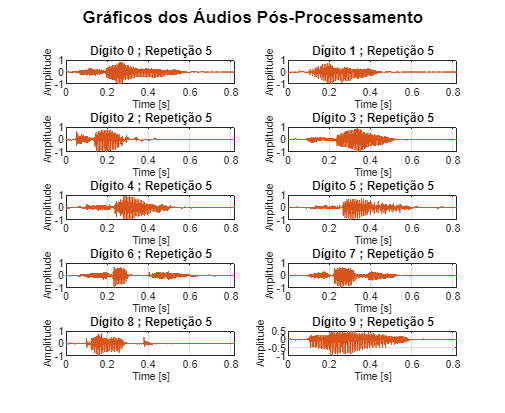


mask_pre   = (T.Repetition == REP_EXAMPLE) & (T.Participant == PART_EXAMPLE);
subset_pre = sortrows(T(mask_pre,:), 'Digit');

figure('Name','Gráficos dos Áudios Pós-Processamento', ...
       'NumberTitle','off', 'Position',[50 50 1100 900]);
sgtitle('Gráficos dos Áudios Pós-Processamento', 'FontSize',13, 'FontWeight','bold');

for i = 1:height(subset_pre)
    sig = subset_pre.SignalPreprocessed{i};
    fs  = subset_pre.SampleRate(i);
    t   = (0:numel(sig)-1) / fs;

    subplot(5, 2, i);
    plot(t, sig, 'Color',[0.85 0.33 0.10], 'LineWidth',0.5);
    title(sprintf('Dígito %d ; Repetição %d', subset_pre.Digit(i), REP_EXAMPLE), ...
          'FontSize',9, 'FontWeight','bold');
    xlabel('Time [s]', 'FontSize',8);
    ylabel('Amplitude', 'FontSize',8);
    xlim([0, t(end)]); grid on;
end


%% ================================================================
%  PONTO 6 – Comparação Visual: Original vs Pré-processado
%  Grelha com os 10 dígitos lado a lado
% ================================================================
fprintf('=== PONTO 6: Comparação Original vs Pré-processado ===\n');

=== PONTO 6: Comparação Original vs Pré-processado ===


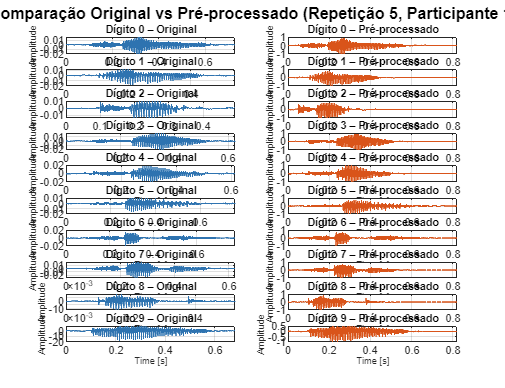


digits_list = sort(unique(T.Digit))';

figure('Name','Comparação Original vs Pré-processado', ...
       'NumberTitle','off', 'Position',[50 50 1300 1000]);
sgtitle('Comparação Original vs Pré-processado (Repetição 5, Participante 1)', ...
        'FontSize',12, 'FontWeight','bold');

for i = 1:numel(digits_list)
    d   = digits_list(i);
    idx = find(T.Digit==d & T.Repetition==REP_EXAMPLE & T.Participant==PART_EXAMPLE, 1);

    fs    = T.SampleRate(idx);
    s_ori = T.Signal{idx};
    s_pre = T.SignalPreprocessed{idx};
    t_ori = (0:numel(s_ori)-1) / fs;
    t_pre = (0:numel(s_pre)-1) / fs;

    subplot(10, 2, 2*i-1);
    plot(t_ori, s_ori, 'Color',[0.18 0.45 0.69], 'LineWidth',0.5);
    title(sprintf('Dígito %d – Original', d), 'FontSize',8, 'FontWeight','bold');
    xlabel('Time [s]','FontSize',7); ylabel('Amplitude','FontSize',7);
    xlim([0, t_ori(end)]); grid on;

    subplot(10, 2, 2*i);
    plot(t_pre, s_pre, 'Color',[0.85 0.33 0.10], 'LineWidth',0.5);
    title(sprintf('Dígito %d – Pré-processado', d), 'FontSize',8, 'FontWeight','bold');
    xlabel('Time [s]','FontSize',7); ylabel('Amplitude','FontSize',7);
    xlim([0, t_pre(end)]); grid on;
end


fprintf(['  Observações:\n' ...
    '  - Silêncio inicial removido: todos os sinais começam no onset da fala.\n' ...
    '  - Amplitude normalizada em [-1, 1]: elimina variações de ganho.\n' ...
    '  - Duração uniforme: %d amostras (%.3f s) para todos os sinais.\n\n'], ...
    target_len, target_len / T.SampleRate(1));

  Observações:
  - Silêncio inicial removido: todos os sinais começam no onset da fala.
  - Amplitude normalizada em [-1, 1]: elimina variações de ganho.
  - Duração uniforme: 39345 amostras (0.820 s) para todos os sinais.




%% ================================================================
%  PONTO 7 – Características Temporais (7 features por áudio)
%
%  T1 – Energia total
%  T2 – Amplitude máxima absoluta
%  T3 – Desvio padrão da amplitude
%  T4 – Zero-Crossing Rate (ZCR)
%  T5 – Razão de energia: 1ª metade / 2ª metade
%  T6 – Energia no onset (primeiros 25%)
%  T7 – Root Mean Square (RMS)
% ================================================================
fprintf('=== PONTO 7: Cálculo de features temporais ===\n');

=== PONTO 7: Cálculo de features temporais ===



feat_energy_total = zeros(N_files, 1);
feat_amp_max      = zeros(N_files, 1);
feat_amp_std      = zeros(N_files, 1);
feat_zcr          = zeros(N_files, 1);
feat_energy_ratio = zeros(N_files, 1);
feat_energy_onset = zeros(N_files, 1);
feat_rms          = zeros(N_files, 1);

for i = 1:N_files
    sig  = T.SignalPreprocessed{i};
    n    = numel(sig);
    half = floor(n / 2);
    q1   = floor(n / 4);

    feat_energy_total(i)  = sum(sig .^ 2);
    feat_amp_max(i)       = max(abs(sig));
    feat_amp_std(i)       = std(sig);
    feat_zcr(i)           = sum(abs(diff(sign(sig)))) / (2 * n);

    e1 = sum(sig(1:half) .^ 2) + 1e-12;
    e2 = sum(sig(half+1:end) .^ 2) + 1e-12;
    feat_energy_ratio(i)  = e1 / e2;

    feat_energy_onset(i)  = sum(sig(1:q1) .^ 2);
    feat_rms(i)           = sqrt(mean(sig .^ 2));
end

T.FeatEnergyTotal = feat_energy_total;
T.FeatAmpMax      = feat_amp_max;
T.FeatAmpStd      = feat_amp_std;
T.FeatZCR         = feat_zcr;
T.FeatEnergyRatio = feat_energy_ratio;
T.FeatEnergyOnset = feat_energy_onset;
T.FeatRMS         = feat_rms;

fprintf('  Features temporais calculadas para %d áudios.\n', N_files);

  Features temporais calculadas para 30000 áudios.


fprintf('  Colunas adicionadas: FeatEnergyTotal, FeatAmpMax, FeatAmpStd,\n');

  Colunas adicionadas: FeatEnergyTotal, FeatAmpMax, FeatAmpStd,


fprintf('                       FeatZCR, FeatEnergyRatio, FeatEnergyOnset, FeatRMS\n\n');

                       FeatZCR, FeatEnergyRatio, FeatEnergyOnset, FeatRMS



fprintf('Pontos 1 a 7 concluídos.\n');

Pontos 1 a 7 concluídos.



%% ================================================================
%  FUNÇÕES LOCAIS – OBRIGATORIAMENTE NO FINAL DO FICHEIRO
% ================================================================

function sig_out = remove_silence(sig, fs, window_ms, thresh)
% Remove o silêncio inicial com base na energia por janelas.
    win_samples = round(fs * window_ms / 1000);
    n_frames    = floor(numel(sig) / win_samples);

    if n_frames == 0, sig_out = sig; return; end

    energies = zeros(n_frames, 1);
    for k = 1:n_frames
        frame       = sig((k-1)*win_samples+1 : k*win_samples);
        energies(k) = sum(frame .^ 2);
    end

    max_e = max(energies);
    if max_e == 0, sig_out = sig; return; end

    onset = find(energies / max_e > thresh, 1, 'first');
    if isempty(onset), sig_out = sig; return; end

    sig_out = sig((onset-1)*win_samples+1 : end);
end


function sig_out = norm_amplitude(sig)
% Normaliza o sinal para [-1, 1] com base no máximo absoluto.
    mv = max(abs(sig));
    if mv == 0, sig_out = sig; return; end
    sig_out = sig / mv;
end


function sig_out = pad_trim(sig, target_len)
% Corta ou adiciona zeros no final para atingir target_len amostras.
    if numel(sig) >= target_len
        sig_out = sig(1:target_len);
    else
        sig_out = [sig; zeros(target_len - numel(sig), 1)];
    end
end